close all
load exp2Msim
load exp2Msetup

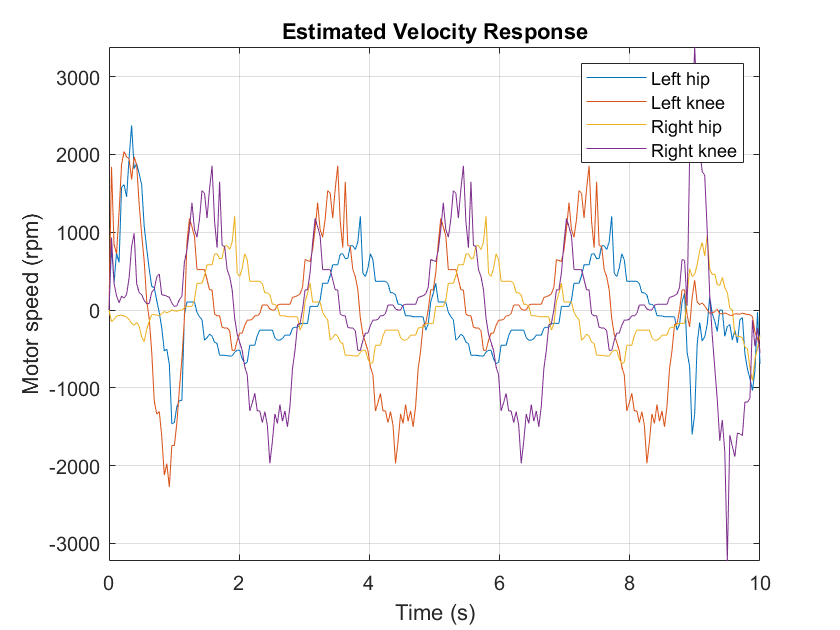

a = 1.6875e-4;
theta_f = 0;
theta_i = 0;
theta__dot_f = 0;
theta__dot_i = 0;
theta__ddot_i = 0;

theta = JointTrajFit(sm_t1,a,t_f,theta_f,theta_i,theta__dot_f,theta__dot_i,theta__ddot_i);

sm_veltraj = convangvel(diff(100*sm_traj1)/sm_t1(2),'rad/s','rpm');
sm_veltraj = [zeros(1,size(sm_veltraj,2)); sm_veltraj];

f1 = figure;
plot(sm_t1, sm_veltraj)
legend('Left hip','Left knee','Right hip','Right knee')
title('Estimated Velocity Response')
xlabel('Time (s)'), ylabel('Motor speed (rpm)')
grid on, axis tight

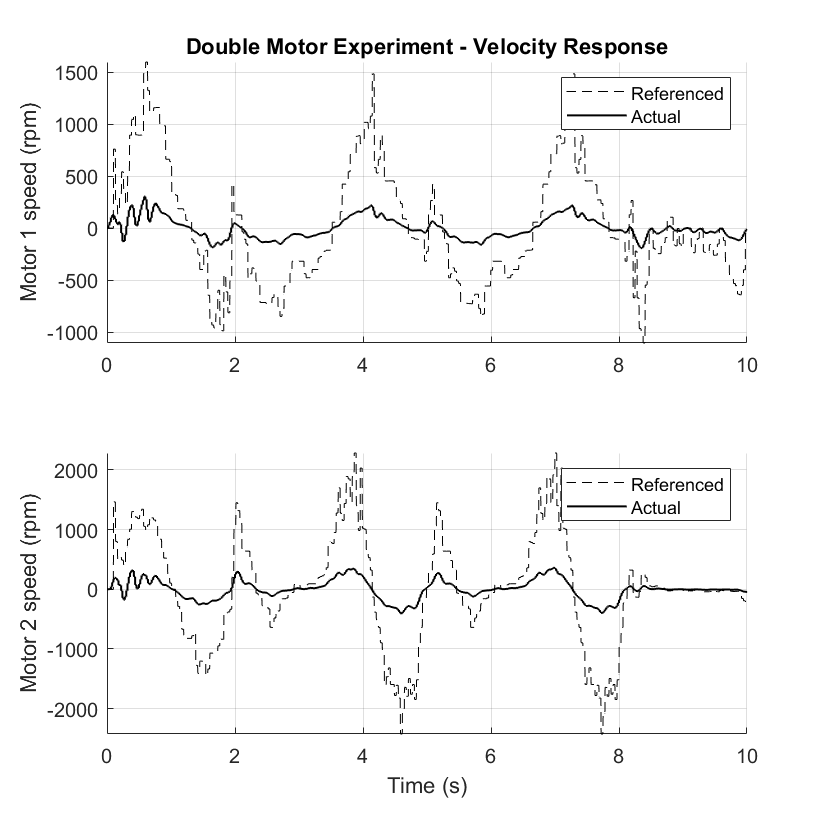

Motor1VelRef = simOut1.logsout{1}.Values.signal1;
Motor1VelAct = simOut1.logsout{1}.Values.Speed;
Motor2VelRef = simOut1.logsout{2}.Values.signal1;
Motor2VelAct = simOut1.logsout{2}.Values.Speed;

f2 = figure;
f2.Position = [10 10 550 550];

subplot(2,1,1), hold on
plot(Motor1VelRef,'k--')
plot(Motor1VelAct,'k-','LineWidth',1)
title('Double Motor Experiment - Velocity Response')
legend('Referenced','Actual')
xlabel(''), ylabel('Motor 1 speed (rpm)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
plot(Motor2VelRef,'k--')
plot(Motor2VelAct,'k-','LineWidth',1)
legend('Referenced','Actual')
xlabel('Time (s)'), ylabel('Motor 2 speed (rpm)')
grid on, axis tight, hold off

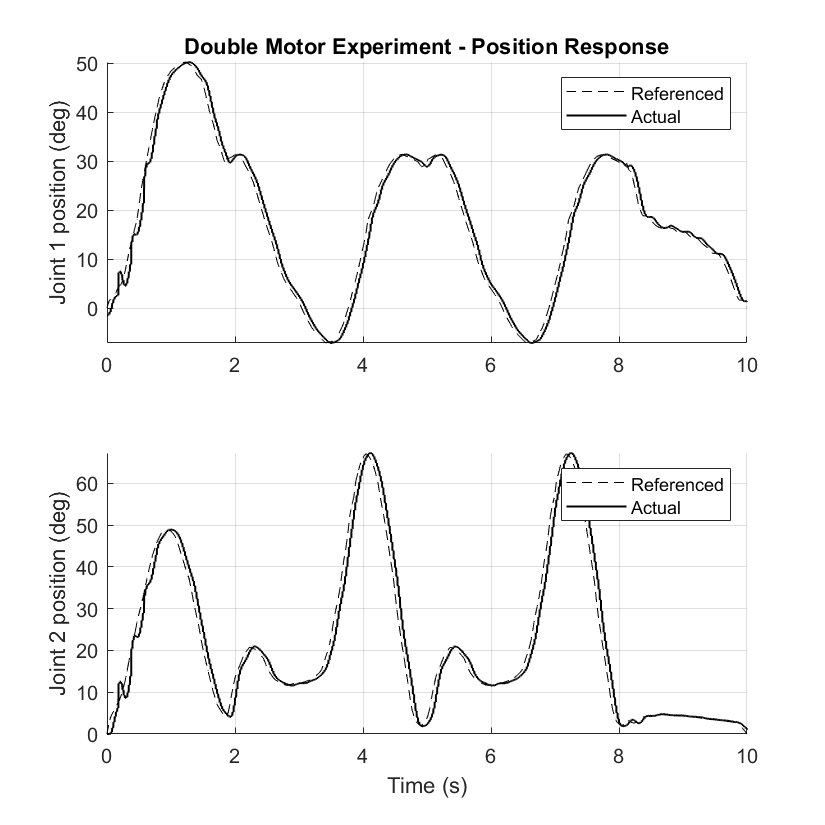



Motor1Pos = simOut1.logsout{5}.Values;
Motor2Pos = simOut1.logsout{6}.Values;
Motor1Cur = simOut1.logsout{3}.Values;
Motor2Cur = simOut1.logsout{4}.Values;

f3 = figure;
f3.Position = [10 10 550 550];

subplot(2,1,1), hold on
p = plot(Motor1Pos,'Color','black');
p(1).LineStyle = '--';
p(2).LineWidth = 1;
title('Double Motor Experiment - Position Response')
legend('Referenced','Actual')
xlabel(''), ylabel('Joint 1 position (deg)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
p = plot(Motor2Pos,'Color','black');
p(1).LineStyle = '--';
p(2).LineWidth = 1;
legend('Referenced','Actual')
xlabel('Time (s)'), ylabel('Joint 2 position (deg)')
grid on, axis tight, hold off

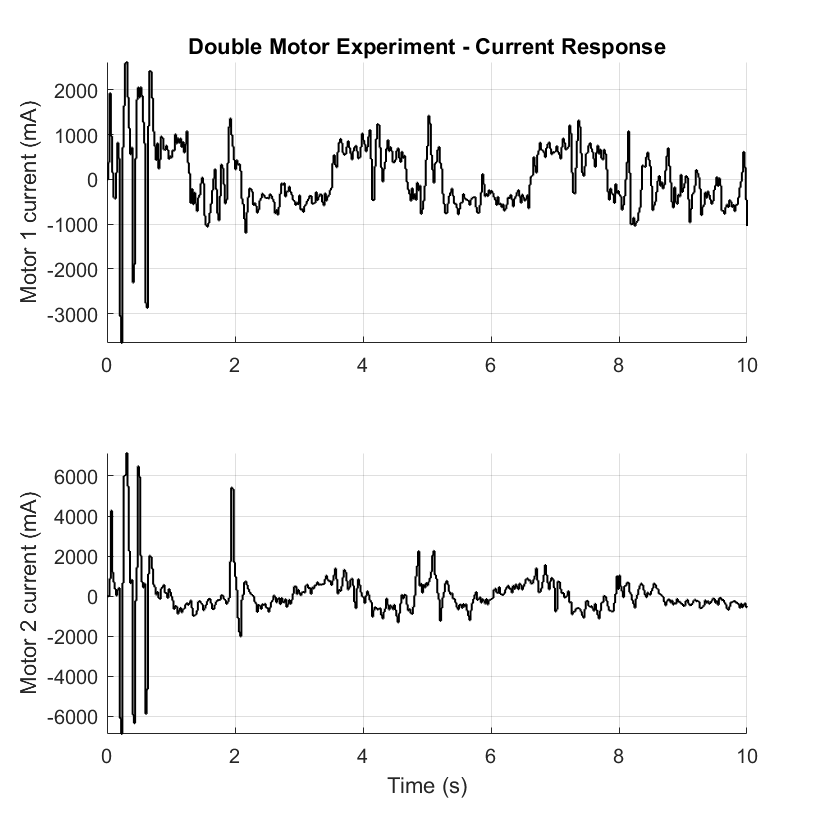

f4 = figure;
f4.Position = [10 10 550 550];

subplot(2,1,1), hold on
plot(Motor1Cur,'k-','LineWidth',1);
title('Double Motor Experiment - Current Response')
xlabel(''), ylabel('Motor 1 current (mA)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
plot(Motor2Cur,'k-','LineWidth',1);
xlabel('Time (s)'), ylabel('Motor 2 current (mA)')
grid on, axis tight, hold off

set(gcf,'DefaultFigureVisible','off')
exportgraphics(f1,'Tests/Exp_2MaxonMotors/Est_4JointsVel.png','Resolution',600); clf

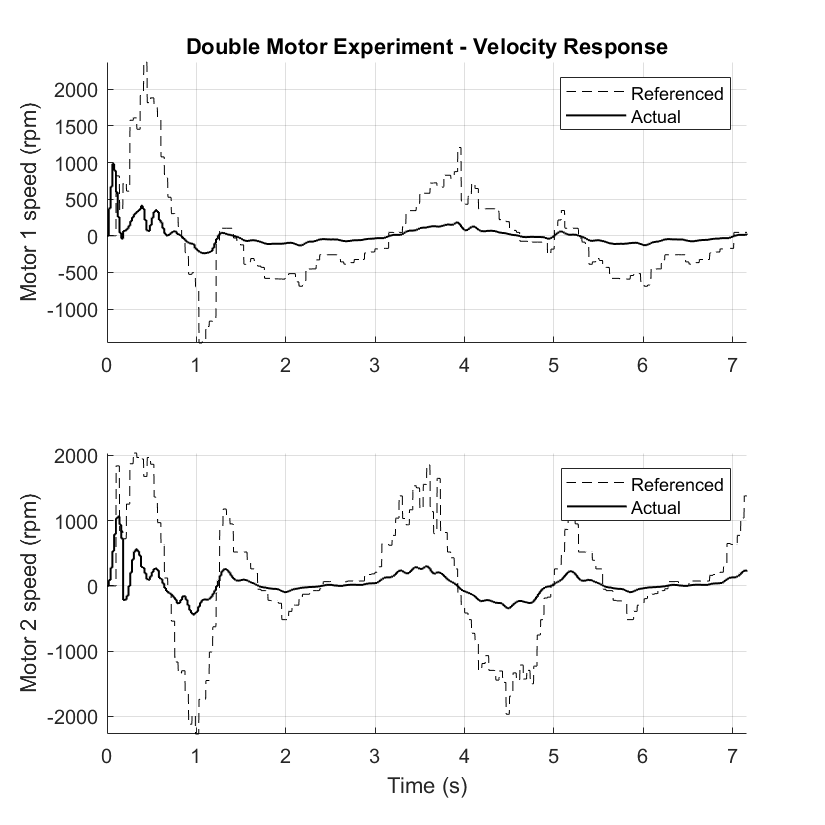

exportgraphics(f2,'Tests/Exp_2MaxonMotors/exp2Mfig_Vel.png','Resolution',600);

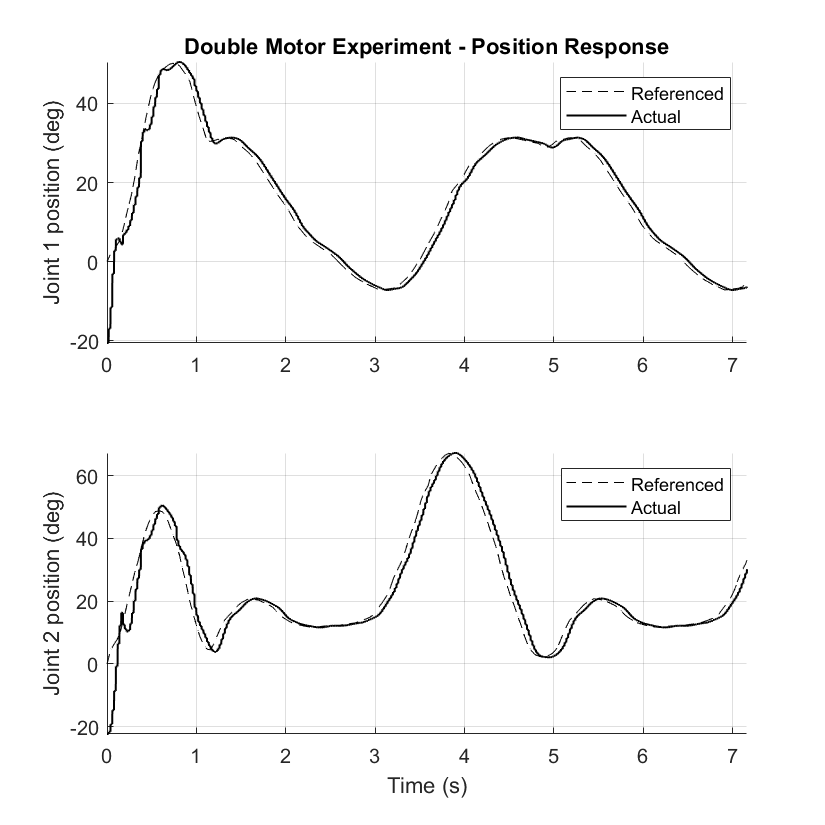

exportgraphics(f3,'Tests/Exp_2MaxonMotors/exp2Mfig_Pos.png','Resolution',600);

exportgraphics(f4,'Tests/Exp_2MaxonMotors/exp2Mfig_Cur.png','Resolution',600);
set(gcf,'DefaultFigureVisible','on')
